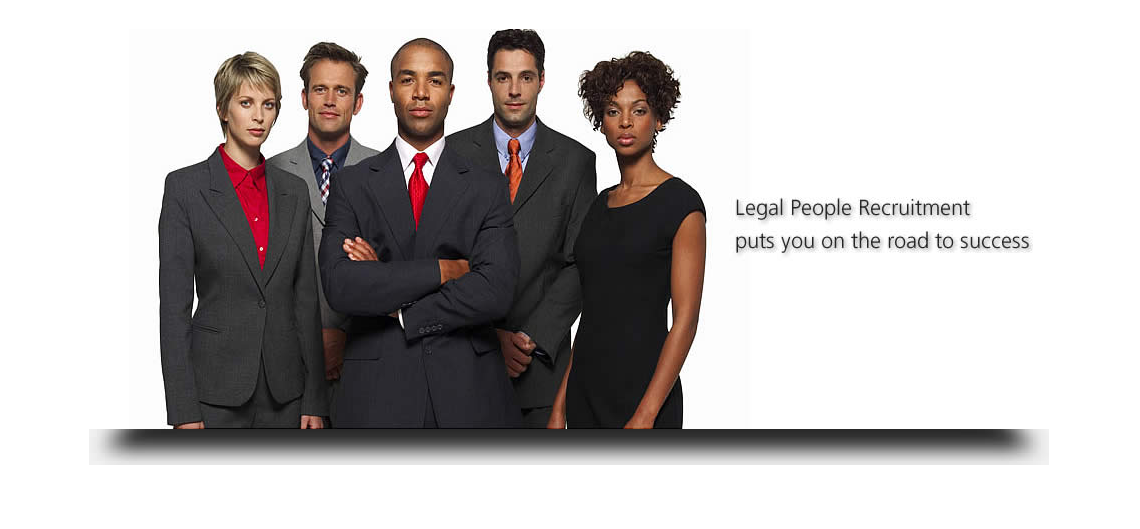

faceDetector = vision.CascadeObjectDetector();
I = imread('banner_3.jpg');
imshow(I)

bboxes = faceDetector(I)

bboxes =    212    38    61    61
   141    54    58    58
   394    24    65    65
   509    60    58    58
   300    25    69    69


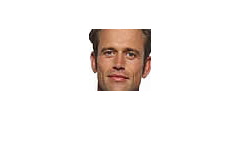

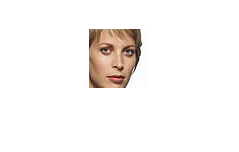

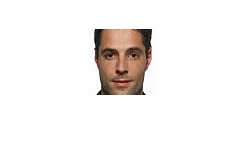

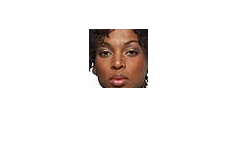

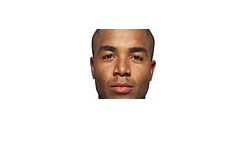


for i=1:length(bboxes)
    figure;
    imshow(  imcrop(I,bboxes(i,:)))
end

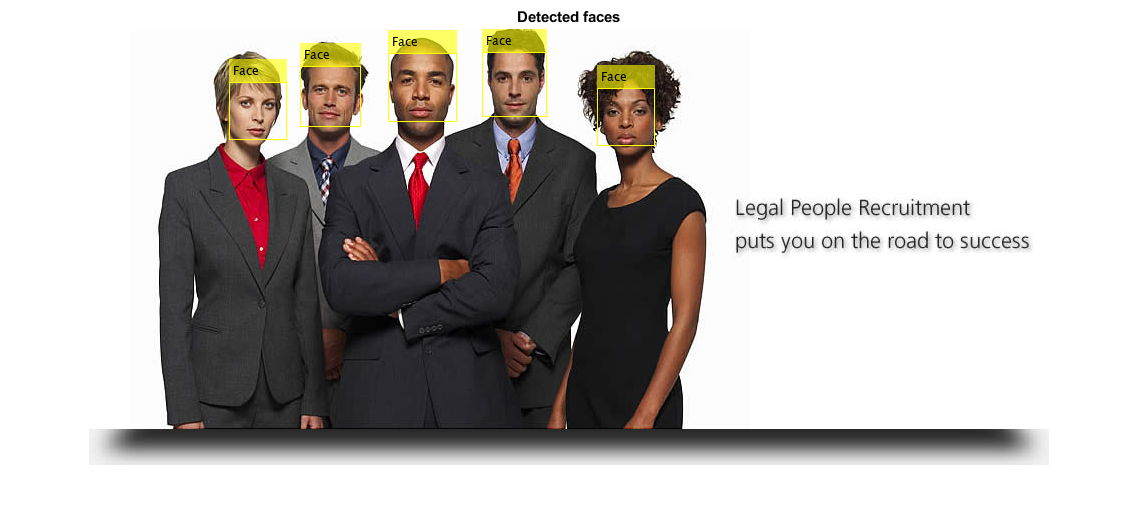


IFaces = insertObjectAnnotation(I,'rectangle',bboxes,'Face');   
figure
imshow(IFaces)
title('Detected faces');